# Transducer Design

Transducer 1

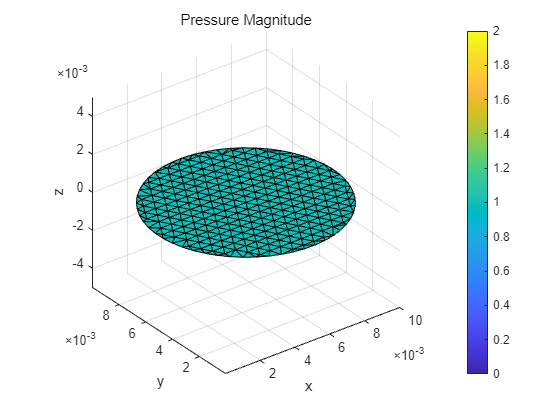

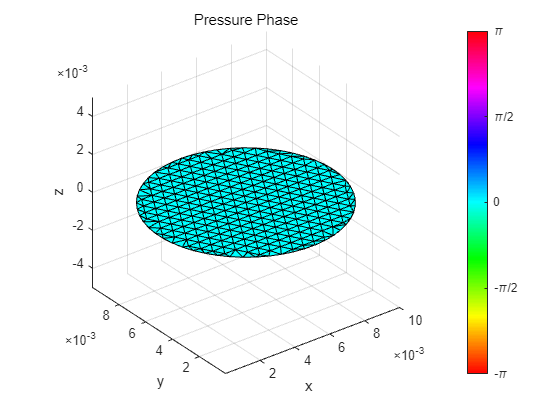

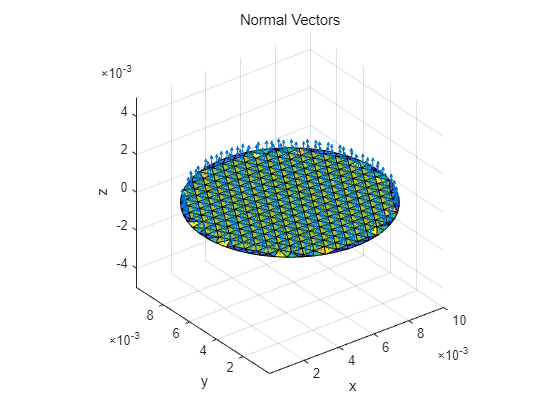

% Define common properties
transducer_info = struct();
transducer_info.Frequency = 4e4;    % 40kHz (operating frequency of transducer)
transducer_info.Pressure = 1;       % How to set this parameter?
transducer_info.Type = 'circle';
transducer_info.Radius = 5e-3;      
transducer_info.rotate = [0, 0, 0];
transducer_info.medium = 'air';

transducer_info.position = [5e-3,5e-3,0];
transducer_info.Phase = 0;
transducer_object(1) = PFC_Make3DTransducer(transducer_info);

%%%%%%%%%%%%%%%%%%%%%%%%%%
% Positions and phases for the transducers (1 row)
% positions = [];
% for k = 1:32
%     positions(k) = 0.005 + 0.01 * (k-1);
% end
% PFC_PhaseCalculate(target[x,y], array, focal point z(m))
%phases = PFC_PhaseCalculate([0.08, 0], [1,16], 0.03)

% % Counter for linear indexing into transducer_object
% index = 1;
% 
% % Populate the transducer objects
% %for i = 1:4
%     for j = 1:32
%         % Update position and phase
%         transducer_info.position = [positions(j), 0, 0];
%         % transducer_info.Phase = phases(j);
%         transducer_info.Phase = 0;
%         transducer_object(index) = PFC_Make3DTransducer(transducer_info);
% 
%         % Increment index for next transducer
%         index = index + 1;
%     end
% %end
%%%%%%%%%%%%%%%%%%%%%%%%


% Draw all transducers in 3D once
PFC_DrawTransducer3D(transducer_object, '-');

## Frequency Domain

input_source.Type = 'frequency';
input_source.reading_list = 1e6; % [Hz]

## Simulation Space

reading_pos_x = -10e-3 : 0.1e-3 : 20e-3;          % Simulation Area
reading_pos_y = -10e-3 : 0.1e-3 : 20e-3;          % Simulation Area
reading_pos_z = 0 : 0.1e-3 : 400e-3;          % Simulation Area

## Run Frequency Domain Simulation

% xz plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, 0.005, reading_pos_z);

Started at 2024-08-05 19:41:59
Finished at 2024-08-05 19:43:29
Progressed time : 00:01:29


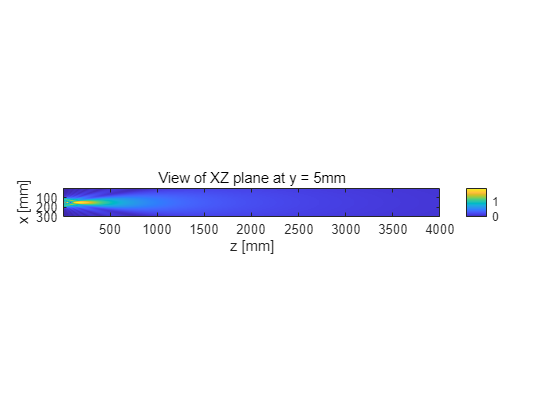


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

% figure;imagesc(reading_pos_x.*1e3, reading_pos_z.*1e3, Pressure_dxyz_i);
figure;imagesc(Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XZ plane at y = 5mm');
colorbar;
xlabel('z [mm]');
ylabel('x [mm]');



% yz plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    0.005, reading_pos_y, reading_pos_z);

Started at 2024-08-05 19:43:29
Finished at 2024-08-05 19:46:35
Progressed time : 00:03:06


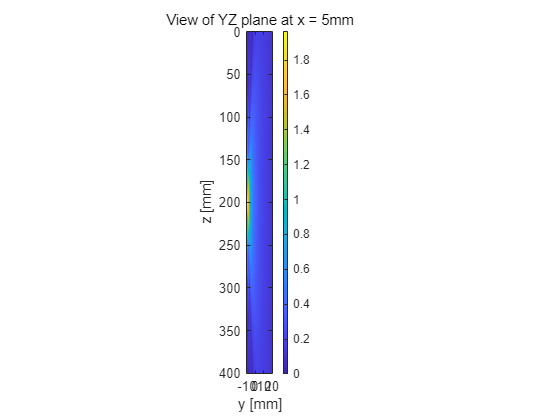


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_y.*1e3, reading_pos_z.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of YZ plane at x = 5mm');
colorbar;
xlabel('y [mm]');
ylabel('z [mm]');